绘制带有关键时点标识的渐淡线图

## 语法

## 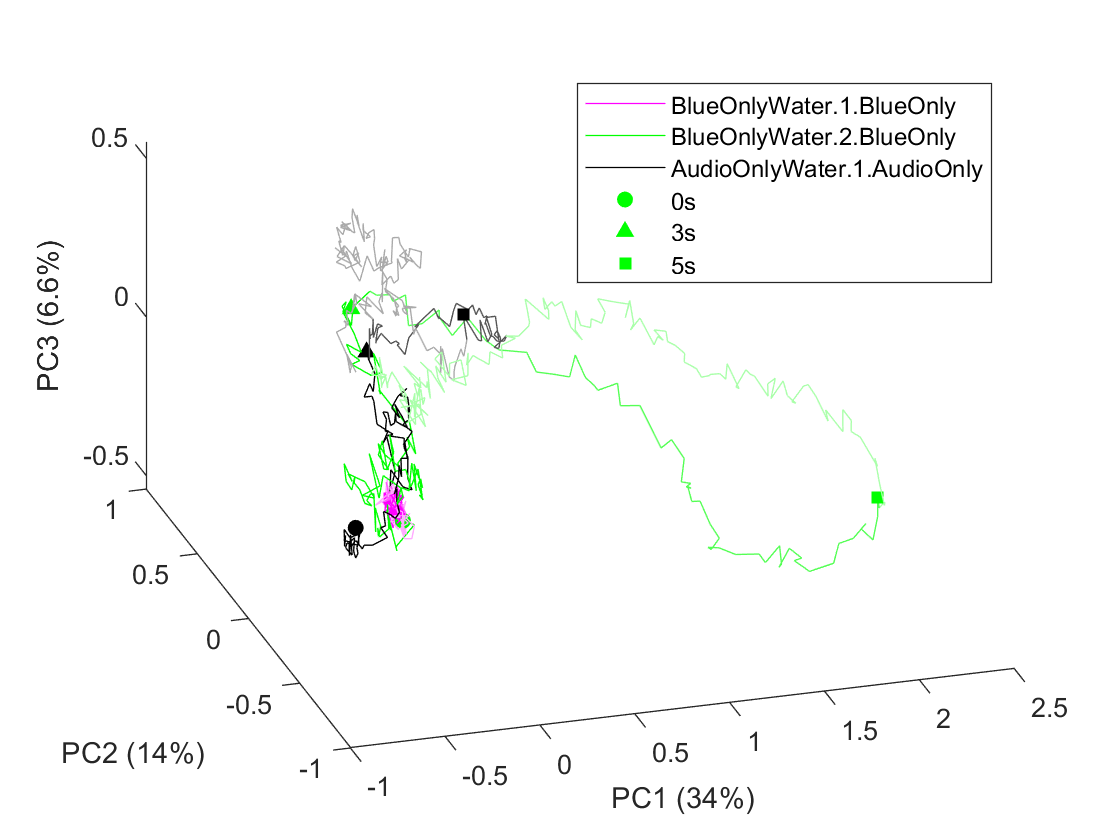

## 输入参数

Points(:,:,2:3)double，线上采样点的坐标。第1维时间，第2维不同的线，第3维XYZ。根据第3维长度决定画2D还是3D图。

LineColors(:,3)double，线条颜色。第1维不同的线，第2维RGB，数值范围0~1。

KeyIndex(1,:)uint16，关键时点位置。这里的时点是采样时点索引，不是真实时间。通常需要用真实时间×采样率。线条每经过一个关键时点都会向白色方向线性减淡。如果不指定此参数，则不会渐淡。

KeyMarkers(1,:)char，对应每个KeyIndex位置，在线条上额外增加指定的符号标注。此功能依赖scatter或scatter3实现，详见Scatter.Marker属性文档。如不指定此参数，将不显示符号标注。

### 名称值参数

PatchArguments(1,:)cell，额外传递给patch的名称值参数。本函数调用patch绘制渐淡线条，此处传递额外参数以控制线条样式细节。

ScatterArguments(1,:)cell，额外传递给scatter或scatter3的名称值参数。本函数调用scatter或scatter3绘制符号标注，此处传递额外参数以控制标注样式细节。

## 返回值

Lines(:,1)matlab.graphics.primitive.Patch，对应每根线返回一个Patch对象，可用于legend函数显示图例或其它后期编辑

Scatters(:,1)matlab.graphics.chart.primitive.Scatter，对应每个关键时点返回一个Scatter对象，可用于legend函数显示图例或其它后期编辑。必须指定KeyMarkers参数才有此返回值。

**See also** [patch](matlab:doc patch) [scatter](matlab:doc scatter) [scatter3](matlab:doc scatter3) [matlab.graphics.chart.primitive.Scatter](matlab:doc matlab.graphics.chart.primitive.Scatter) [matlab.graphics.primitive.Patch](matlab:doc matlab.graphics.primitive.Patch) [legend](matlab:doc legend)

function [Lines,Scatters]=SegmentFadePlot(Points,LineColors,KeyIndex,KeyMarkers,options)
arguments
	Points %此处有可能输入gpuArray，因此不能限制double类型
	LineColors
	KeyIndex=[]
	KeyMarkers char=''
	options.PatchArguments={}
	options.ScatterArguments={}
end
[NumTime,NumLines,NumDimensions]=size(Points);
if ~isempty(KeyIndex)
	NumKeys=numel(KeyIndex);
	ColorKey=KeyIndex;
	if ColorKey(1)==1
		ColorKey(1)=[];
	end
	if ColorKey(end)<NumTime
		ColorKey(end+1)=NumTime;
	end
	ColorKey(2:end)=ColorKey(2:end)-ColorKey(1:end-1);
else
	ColorKey=NumTime;
end
NumColors=numel(ColorKey)+1;
Colors=MATLAB.ElMat.LinSpace(shiftdim(LineColors,-1),1,NumColors,1);
ColorMap=cell(NumColors,1);
for C=1:NumColors-1
	ColorMap{C}=repmat(Colors(C,:,:),ColorKey(C),1,1);
end
ColorMap{end}=Colors(end,:,:);
ColorMap=vertcat(ColorMap{:});
Points(end+1,:,:)=NaN;
%虽然可以一个patch搞定，但为了画图例必须分开
Lines=gobjects(NumLines,1);
switch NumDimensions
	case 2
		for L=1:NumLines
			Lines(L)=patch(Points(:,L,1),Points(:,L,2),ColorMap(:,L,:),options.PatchArguments{:},EdgeColor='flat',FaceColor='none');%FaceColor设为none才能让图例显示为线条
		end
	case 3
		for L=1:NumLines
			Lines(L)=patch(Points(:,L,1),Points(:,L,2),Points(:,L,3),ColorMap(:,L,:),options.PatchArguments{:},EdgeColor='flat',FaceColor='none');
		end
	otherwise
		UniExp.UniExpException.Wrong_array_size.Throw('LinePoints第3维长度只能是2或3');
end
if ~isempty(KeyMarkers)
	Points=Points(KeyIndex,:,:);
	Scatters=gobjects(NumKeys,1);
	HoldState=ishold;
	hold on
	switch NumDimensions
		case 2
			for K=1:NumKeys
				Scatters(K)=scatter(Points(K,:,1),Points(K,:,2),KeyMarkers(K),options.ScatterArguments{:},MarkerEdgeColor='none',MarkerFaceColor='flat',CData=LineColors);
			end
		case 3
			for K=1:NumKeys
				Scatters(K)=scatter3(Points(K,:,1),Points(K,:,2),Points(K,:,3),KeyMarkers(K),options.ScatterArguments{:},MarkerEdgeColor='none',MarkerFaceColor='flat',CData=LineColors);
			end
	end
	if ~HoldState
		hold off
	end
end